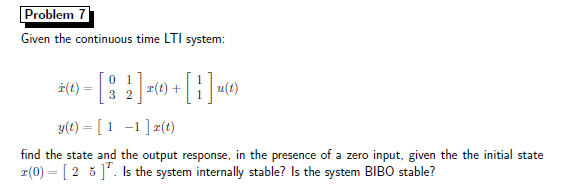

A=[0 1;3 2];
B=[1 1]';
C=[1 -1];
D=[0];
X0=[2 5]';

sys=ss(A,B,C,D);
s=tf('s');
H=tf(sys)

H =
 
       -4
  -------------
  s^2 - 2 s - 3
 
Continuous-time transfer function.




U=1/s;
Y=minreal((zpk(C*inv(s*eye(2)-A)*B*U+D*U)),1e-3);
[numY,denY]=tfdata(Y,'v');  %v because I need a vectorial format

[r,p]=residue(numY,denY) %the residues are the numerators and p are the poles

r =    -0.3333
   -0.0000
    0.0000
   -0.0000
   -1.0000
   -0.0000
   -0.0000
   -0.0000
    1.3333


p =     3.0000
    3.0000
    3.0000
    3.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
         0




pole(H)

ans =     3.0000
   -1.0000


rlocus(H(1),'b')


There is a positive eigenvalue so the system is unstable and divergent.

## **SIMBOLIC METHOD**

H

H =
 
       -4
  -------------
  s^2 - 2 s - 3
 
Continuous-time transfer function.



clear
syms t f(t) H s h(t)

H=(-4)/((s^2-2*s-3))

$$H = \frac{4}{-s^{2}+2\,s+3}$$

partfrac(H)

$$ans = \frac{1}{s+1}-\frac{1}{s-3}$$

h(t) = vpa(ilaplace(H,s,t))

$$h(t) = {\mathrm{e}}^{-1.0\,t}-1.0\,{\mathrm{e}}^{3.0\,t}$$

f(t)=2

$$f(t) = 2$$

assume(t,'positive')
y=vpa(simplify(ilaplace(laplace(f)*H)),4)

$$y = 2.667-0.6667\,{\mathrm{e}}^{3.0\,t}-2.0\,{\mathrm{e}}^{-1.0\,t}$$

% fplot(y)